# **Materials classification - A1**

# Convolutional neural networks

clc; clear all; close all;

## Import dataset

rng(100)

% Training and test images
train_image_data_folder = "Data\Train\image\";
test_image_data_folder = "Data\Test\image\";

imds = imageDatastore(train_image_data_folder,'IncludeSubFolders',true,'FileExtensions','.jpg','LabelSource','foldernames');
[trainImds,valImds] = splitEachLabel(imds,0.9);

### Create image set

% The training set consists of 810 images (81 images/ class) and
% the validation set consists of 90 images (9 images/ class)
countEachLabel(trainImds)

ans = 10×2 table
     Label     Count
    _______    _____

    fabric      81  
    foliage     81  
    glass       81  
    leather     81  
    metal       81  
    paper       81  
    plastic     81  
    stone       81  
    water       81  
    wood        81  


countEachLabel(valImds)

ans = 10×2 table
     Label     Count
    _______    _____

    fabric       9  
    foliage      9  
    glass        9  
    leather      9  
    metal        9  
    paper        9  
    plastic      9  
    stone        9  
    water        9  
    wood         9  


### Convolutional Deep Network

% augmenter = imageDataAugmenter('RandRotation',[0 180],'RandXTranslation', [-5 5], ...
%     'RandYTranslation',[-5 5]);
augimds = augmentedImageDatastore([300 300 3],trainImds, 'ColorPreprocessing',"gray2rgb");

% CNN
layers = [
    imageInputLayer([300 300 3])
    convolution2dLayer(32,16)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(16,8)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(4,2)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(4)
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

opts = trainingOptions('sgdm',...
    'InitialLearnRate',  0.01, ...
    'MaxEpochs', 50, ...
    'MiniBatchSize',10,...
    'Shuffle','every-epoch',...
    'Plots', 'training-progress',...
    'Verbose',false,...
    'ExecutionEnvironment','gpu');

% trainedNet = trainNetwork(augimds,layers,opts);

net = squeezenet;
lgraphSQZ = layerGraph(net);
numClasses = numel(categories(trainImds.Labels));
oldFinalConv = lgraphSQZ.Layers(end-4);
newFinalConv = convolution2dLayer(1,numClasses, ...
        'Name','new_conv');
setLearnRateFactor(newFinalConv,'Weights',10);
setLearnRateFactor(newFinalConv,'Bias',10)

ans =   Convolution2DLayer with properties:

              Name: 'new_conv'

   Hyperparameters
        FilterSize: [1 1]
       NumChannels: 'auto'
        NumFilters: 10
            Stride: [1 1]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [0 0 0 0]
      PaddingValue: 0

   Learnable Parameters
           Weights: []
              Bias: []

  Show all properties


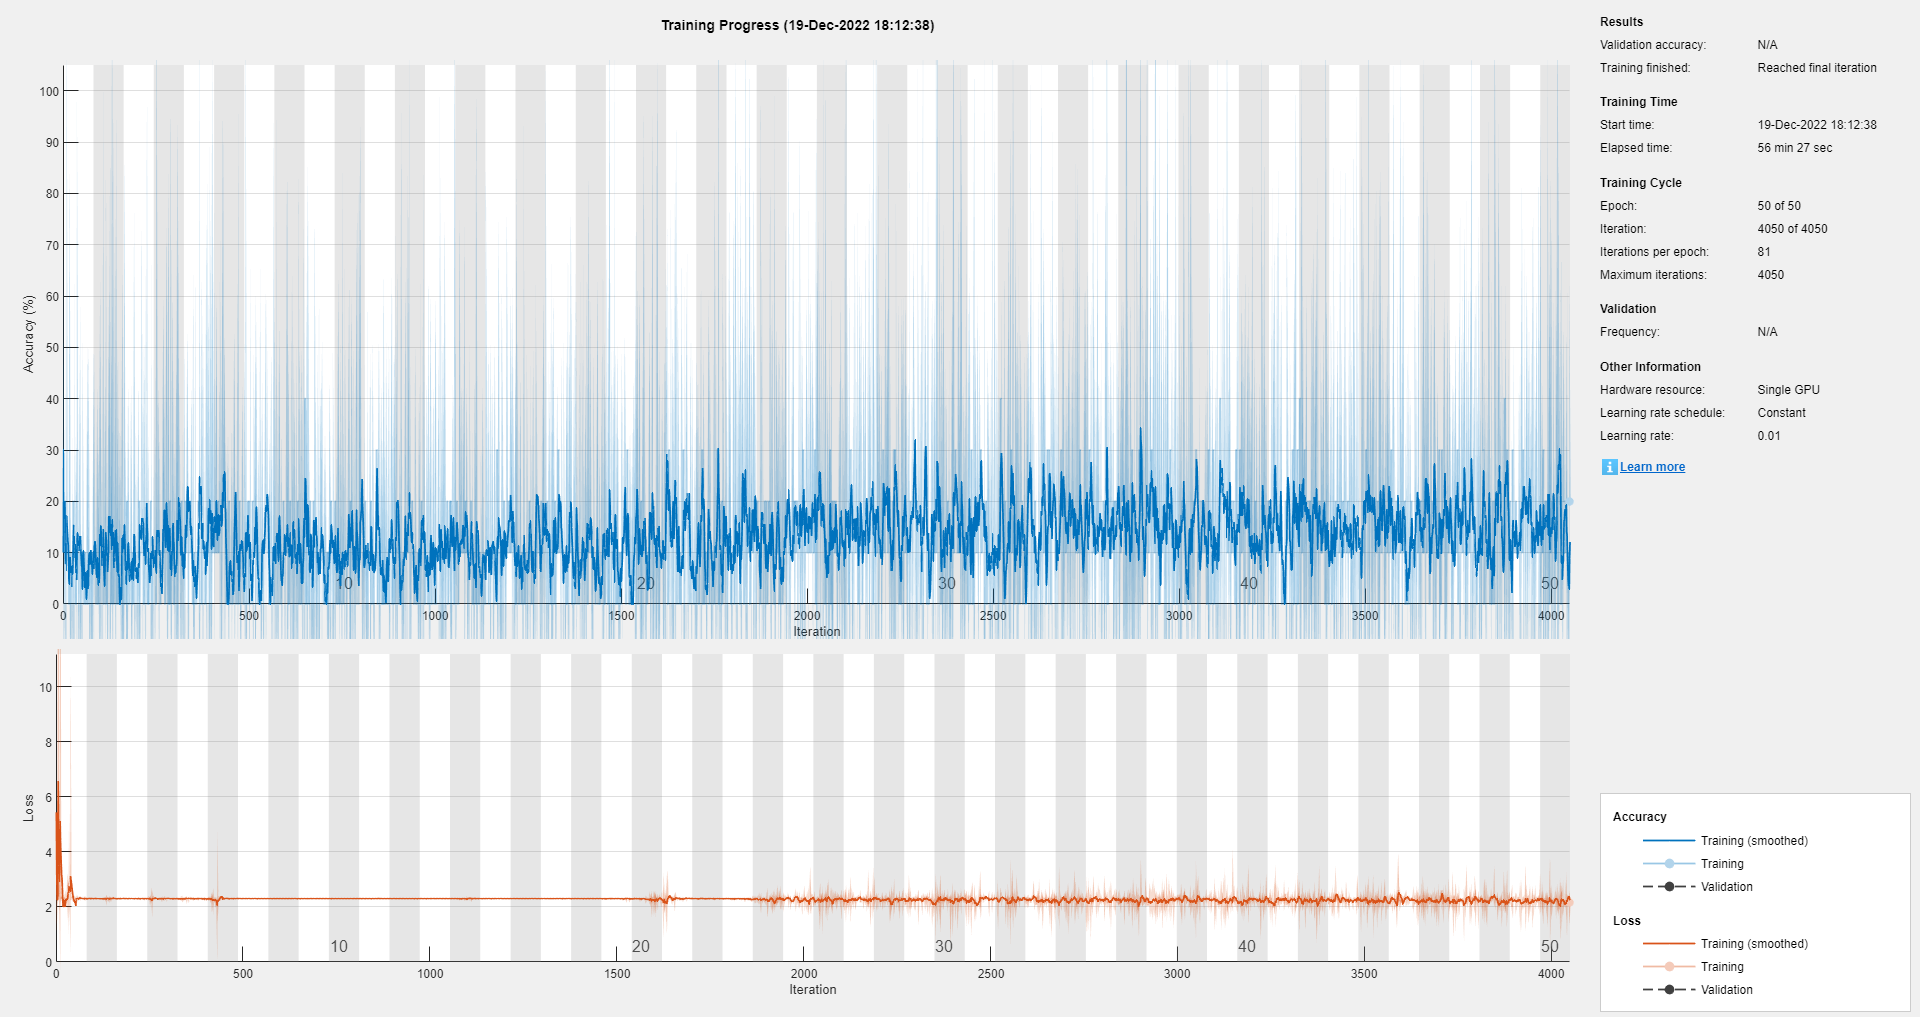


lgraphSQZ = replaceLayer(lgraphSQZ,oldFinalConv.Name,newFinalConv);
oldClassLayer= lgraphSQZ.Layers(end);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSQZ = replaceLayer(lgraphSQZ,oldClassLayer.Name,newClassLayer);

reset(trainImds);
reset(valImds);
trainImds.ReadFcn = @(x)imresize(imread(x),'OutputSize',[227 227]);
valImds.ReadFcn = @(x)imresize(imread(x),'OutputSize',[227 227]);
augmenter = imageDataAugmenter('RandRotation',[0 180],'RandXTranslation', [-5 5], ...
    'RandYTranslation',[-5 5]);
augimds = augmentedImageDatastore([227 227 3],trainImds,...
    'DataAugmentation',augmenter, 'ColorPreprocessing','gray2rgb');
trainedNet = trainNetwork(augimds,lgraphSQZ,opts);


ypred = trainedNet.classify(valImds);
cnnAccuracy = sum(ypred == valImds.Labels)/numel(valImds.Labels)*100

cnnAccuracy = 10

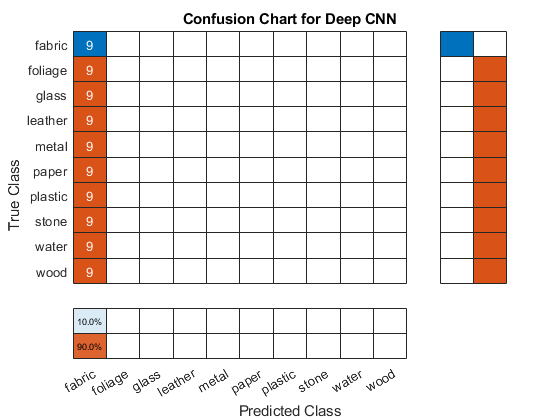



figure
cchart = confusionchart(valImds.Labels,ypred);
cchart.Title = 'Confusion Chart for Deep CNN';
cchart.RowSummary = 'row-normalized';
cchart.ColumnSummary = 'column-normalized';